## Q2 - part d - Box-Jenkins

clc; clear;

%%

load HW5_question2

u3 = Z3.u;
y3 = Z3.y;

u3_val = u3;%(601:end);
y3_val = y3;%(601:end);

u3 = u3(1:600);
y3 = y3(1:600);



%%

% System Z3 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System III Identification Begins:------------------------------\n")

>>> System III Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u3)*Ts-Ts;
t_val = 0:Ts:length(u3_val)*Ts-Ts;
N = length(y3);
N_val = length(y3_val);

data3 = iddata(y3,u3,Ts);


%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nd = degree;
    nk = 1;
    p = na+nb+nc+nd;
    
    try
        sys = bj(data3, [na nb nc nd nk]);
        bj_y_hat_3 = lsim(sys, u3, t);
    catch
        break
    end

    [r2_bj, mse_bj] = rSQR(y3, bj_y_hat_3);

    error = y3 - bj_y_hat_3;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_bj, mse_bj, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_bj];
    MSEs = [MSEs; mse_bj];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=-0.006472 | MSE=140.441342 | var=141.383901 | s_hat=84264.804977 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.972050 | MSE=3.900046 | var=3.952749 | s_hat=2340.027667 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.970744 | MSE=4.082400 | var=4.165714 | s_hat=2449.439781 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.997734 | MSE=0.316203 | var=0.324866 | s_hat=189.721601 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.997768 | MSE=0.311455 | var=0.322195 | s_hat=186.872970 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.997793 | MSE=0.307950 | var=0.320781 | s_hat=184.769820 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.997784 | MSE=0.309178 | var=0.324312 | s_hat=185.506656 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.997814 | MSE=0.305089 | var=0.322277 | s_hat=183.053601 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.932754 | MSE=9.383429 | var=9.982371 | s_hat=5630.057487 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.997707 | MSE=0.319992 | var=0.342848 | s_hat=191.995091 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.997427 | MSE=0.359086 | var=0.387503 | s_hat=215.451394 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=-2.755093 | MSE=523.979107 | var=569.542508 | s_hat=314387.464498 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.994961 | MSE=0.703201 | var=0.769928 | s_hat=421.920516 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.997575 | MSE=0.338398 | var=0.373233 | s_hat=203.038680 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.996556 | MSE=0.480636 | var=0.534040 | s_hat=288.381424 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.997672 | MSE=0.324884 | var=0.363676 | s_hat=194.930328 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.997546 | MSE=0.342454 | var=0.386226 | s_hat=205.472194 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.968357 | MSE=4.415401 | var=5.017501 | s_hat=2649.240369 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.997319 | MSE=0.374082 | var=0.428338 | s_hat=224.449055 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.997907 | MSE=0.291998 | var=0.336921 | s_hat=175.198743 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.963669 | MSE=5.069549 | var=5.894825 | s_hat=3041.729590 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.797318 | MSE=28.281844 | var=33.142786 | s_hat=16969.106447 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.675810 | MSE=45.236945 | var=53.429462 | s_hat=27142.166863 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.995749 | MSE=0.593188 | var=0.706177 | s_hat=355.912985 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.450376 | MSE=76.693629 | var=92.032355 | s_hat=46016.177652 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.898308 | MSE=14.189908 | var=17.165212 | s_hat=8513.944915 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.835568 | MSE=22.944616 | var=27.981240 | s_hat=13766.769884 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.560186 | MSE=61.370946 | var=75.456081 | s_hat=36822.567706 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.948144 | MSE=7.235902 | var=8.970127 | s_hat=4341.541395 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.991494 | MSE=1.186848 | var=1.483559 | s_hat=712.108554 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.954219 | MSE=6.388214 | var=8.052371 | s_hat=3832.928634 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.301123 | MSE=97.520121 | var=123.966255 | s_hat=58512.072349 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.988332 | MSE=1.628174 | var=2.087403 | s_hat=976.904462 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.991548 | MSE=1.179364 | var=1.525040 | s_hat=707.618499 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.997807 | MSE=0.305992 | var=0.399120 | s_hat=183.595064 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.984413 | MSE=2.174978 | var=2.861813 | s_hat=1304.986577 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.978059 | MSE=3.061577 | var=4.064041 | s_hat=1836.946455 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.987243 | MSE=1.780036 | var=2.383977 | s_hat=1068.021822 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.997503 | MSE=0.348421 | var=0.470839 | s_hat=209.052462 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.986861 | MSE=1.833435 | var=2.500139 | s_hat=1100.060946 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.997764 | MSE=0.311962 | var=0.429305 | s_hat=187.177176 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.997531 | MSE=0.344542 | var=0.478530 | s_hat=206.725110 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.997436 | MSE=0.357820 | var=0.501617 | s_hat=214.692016 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.948751 | MSE=7.151157 | var=10.119562 | s_hat=4290.694221 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.994530 | MSE=0.763338 | var=1.090482 | s_hat=458.002511 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.988004 | MSE=1.673887 | var=2.414260 | s_hat=1004.332218 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.994910 | MSE=0.710311 | var=1.034434 | s_hat=426.186808 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.988653 | MSE=1.583358 | var=2.328468 | s_hat=950.014770 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.973025 | MSE=3.764033 | var=5.590147 | s_hat=2258.419513 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.891589 | MSE=15.127512 | var=22.691268 | s_hat=9076.507323 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.986171 | MSE=1.929668 | var=2.923739 | s_hat=1157.800508 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.989965 | MSE=1.400214 | var=2.143185 | s_hat=840.128670 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.984684 | MSE=2.137193 | var=3.304937 | s_hat=1282.315726 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.985164 | MSE=2.070145 | var=3.234602 | s_hat=1242.087214 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.985086 | MSE=2.081011 | var=3.285807 | s_hat=1248.606568 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.994162 | MSE=0.814672 | var=1.300008 | s_hat=488.803093 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.992262 | MSE=1.079756 | var=1.741541 | s_hat=647.853385 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.959463 | MSE=5.656398 | var=9.222388 | s_hat=3393.838908 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.995370 | MSE=0.646119 | var=1.065031 | s_hat=387.671162 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.996840 | MSE=0.440894 | var=0.734824 | s_hat=264.536602 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.983705 | MSE=2.273789 | var=3.832228 | s_hat=1364.273275 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.994614 | MSE=0.751589 | var=1.281118 | s_hat=450.953695 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 20 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
nd = bestFitDegree;
nk = 1;
p = na+nb+nc+nd;

BestFitModel_3 = bj(data3, [na nb nc nd nk])

BestFitModel_3 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                          
                                                                                                          
  B(z) = 0.6145 z^-1 + 1.488 z^-2 + 0.83 z^-3 - 0.4696 z^-4 - 0.3811 z^-5 + 0.5697 z^-6 + 0.3122 z^-7     
          - 0.3657 z^-8 + 0.1322 z^-9 + 0.6618 z^-10 - 0.3601 z^-11 - 0.5141 z^-12 + 0.7082 z^-13         
          + 1.113 z^-14 + 0.06209 z^-15 - 0.4 z^-16 + 0.09941 z^-17 + 0.2256 z^-18 - 0.279 z^             
                                                                                   -19 - 0.2058 z^-20     
                                                                                                          
                                                                                                          
  C(z) = 1 - 1.235 z^-1 + 0.2556 z^-2 + 0.1398 z^-3 - 0.1573 z^-4 + 0.3126 z^-5 + 0.03903 z^-6            
          - 0.2334 z

BestFit_y_hat_3 = lsim(BestFitModel_3, u3_val, t_val);
% [bj_BestFit_r2, bj_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 6 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 6 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
nd = minVarIndex;
nk = 1;
p = na+nb+nc+nd;

bj_VarModel_3 = bj(data3, [na nb nc nd nk])

bj_VarModel_3 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                
  B(z) = 0.6122 z^-1 + 1.056 z^-2 + 0.3816 z^-3 - 0.1856 z^-4 - 0.5302 z^-5 - 0.2009 z^-6       
                                                                                                
  C(z) = 1 + 0.5371 z^-1 - 0.219 z^-2 - 0.2607 z^-3 - 0.2039 z^-4 + 0.6426 z^-5 + 0.3419 z^-6   
                                                                                                
  D(z) = 1 + 0.4986 z^-1 - 0.2165 z^-2 - 0.02158 z^-3 + 0.06623 z^-4 + 0.7615 z^-5 + 0.3904 z^-6
                                                                                                
  F(z) = 1 - 1.249 z^-1 + 0.1076 z^-2 + 0.1692 z^-3 + 0.3635 z^-4 + 0.08166 z^-5 - 0.3849 z^-6  
                                                                                                
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=6   nc=6   nd=6   nf=6   nk=1
   Numbe

Var_y_hat_3 = lsim(bj_VarModel_3, u3_val, t_val);
% [bj_Var_r2, bj_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 5 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 5 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
nd = minAICIndex;
nk = 1;
p = na+nb+nc+nd;

bj_AICModel_3 = bj(data3, [na nb nc nd nk])

bj_AICModel_3 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                  
  B(z) = 0.6311 z^-1 + 1.008 z^-2 + 0.2968 z^-3 - 0.4581 z^-4 - 0.5216 z^-5       
                                                                                  
  C(z) = 1 - 0.06572 z^-1 - 0.174 z^-2 - 0.32 z^-3 + 0.0816 z^-4 + 0.6824 z^-5    
                                                                                  
  D(z) = 1 - 0.07638 z^-1 - 0.1269 z^-2 - 0.09488 z^-3 + 0.1981 z^-4 + 0.6785 z^-5
                                                                                  
  F(z) = 1 - 1.306 z^-1 + 0.1415 z^-2 - 0.1006 z^-3 + 1.214 z^-4 - 0.8751 z^-5    
                                                                                  
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=5   nc=5   nd=5   nf=5   nk=1
   Number of free coefficients: 20
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:            

AIC_y_hat_3 = lsim(bj_AICModel_3, u3_val, t_val);
% [bj_AIC_r2, bj_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.19 as


fprintf("    Degree = %d \n", winner)

    Degree = 4 



na = winner;
nb = winner;
nc = winner;
nd = winner;
nk = 1;
p = na+nb+nc+nd;

bj_FTestModel_3 = bj(data3, [na nb nc nd nk])

bj_FTestModel_3 =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t) 
  B(z) = 0.6156 z^-1 + 0.7605 z^-2 - 0.4021 z^-3 - 0.429 z^-4    
                                                                 
  C(z) = 1 - 0.9074 z^-1 + 0.6011 z^-2 - 0.851 z^-3 + 0.8152 z^-4
                                                                 
  D(z) = 1 - 0.9173 z^-1 + 0.6585 z^-2 - 0.6833 z^-3 + 0.802 z^-4
                                                                 
  F(z) = 1 - 1.758 z^-1 + 0.3698 z^-2 + 1.204 z^-3 - 0.774 z^-4  
                                                                 
Sample time: 0.5 seconds
  
Parameterization:
   Polynomial orders:   nb=4   nc=4   nd=4   nf=4   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using BJ on time domain data "data3".  
Fit to estimation data: 95.85% (prediction focus)
FPE: 0.2532, MSE: 0.

FTest_y_hat_3 = lsim(bj_FTestModel_3, u3_val, t_val);
% [bj_FTest_r2, bj_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")

%%

[bj_BestFit_r2_3, bj_BestFit_mse_3] = rSQR(y3_val, BestFit_y_hat_3);
[bj_Var_r2_3, bj_Var_mse_3] = rSQR(y3_val, Var_y_hat_3);
[bj_AIC_r2_3, bj_AIC_mse_3] = rSQR(y3_val, AIC_y_hat_3);
[bj_FTest_r2_3, bj_FTest_mse_3] = rSQR(y3_val, FTest_y_hat_3);


%%

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_BestFit_r2_3, bj_BestFit_mse_3)

    R2 value : 0.9965   | MSE : 0.4529 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Var_r2_3, bj_Var_mse_3)

    R2 value : 0.9965   | MSE : 0.4502 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Cov_r2, bj_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_AIC_r2_3, bj_AIC_mse_3)

    R2 value : 0.9965   | MSE : 0.4554 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_FTest_r2_3, bj_FTest_mse_3)

    R2 value : 0.9964   | MSE : 0.4581 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

bj_BestFitError_3 = y3_val - BestFit_y_hat_3;
bj_VarError_3 = y3_val - Var_y_hat_3;
bj_AICError_3 = y3_val - AIC_y_hat_3;
bj_FTestError_3 = y3_val - FTest_y_hat_3;

for k=0:N_val-1
    bj_BestFit_Ree_3(k+1,1) = AutoCorrelate(bj_BestFitError_3, k);
    bj_Var_Ree_3(k+1,1) = AutoCorrelate(bj_VarError_3, k);
    bj_AIC_Ree_3(k+1,1) = AutoCorrelate(bj_AICError_3, k);
    bj_FTest_Ree_3(k+1,1) = AutoCorrelate(bj_FTestError_3, k);
end

for k=0:N_val-1
    bj_BestFit_Rue_3(k+1,1) = CrossCorrelate(u3_val, bj_BestFitError_3, k);
    bj_Var_Rue_3(k+1,1) = CrossCorrelate(u3_val, bj_VarError_3, k);
    bj_AIC_Rue_3(k+1,1) = CrossCorrelate(u3_val, bj_AICError_3, k);
    bj_FTest_Rue_3(k+1,1) = CrossCorrelate(u3_val, bj_FTestError_3, k);
end



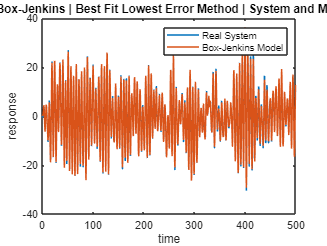

%%
figure(1)
plot(t_val,y3_val,t_val,BestFit_y_hat_3)
legend('Real System','Box-Jenkins Model')
title(" System III : Box-Jenkins | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

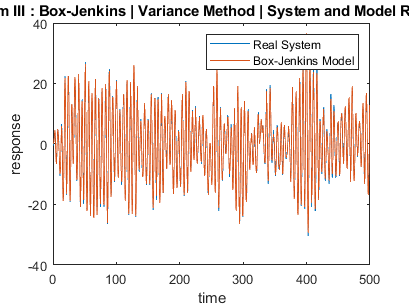


figure(2)
plot(t_val,y3_val,t_val,Var_y_hat_3)
legend('Real System','Box-Jenkins Model')
title(" System III : Box-Jenkins | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

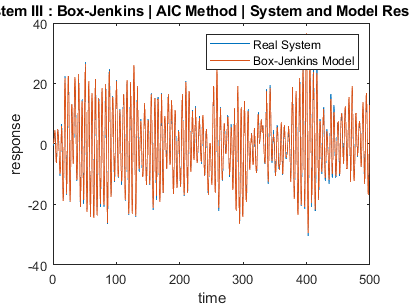


figure(3)
plot(t_val,y3_val,t_val,AIC_y_hat_3)
legend('Real System','Box-Jenkins Model')
title(" System III : Box-Jenkins | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

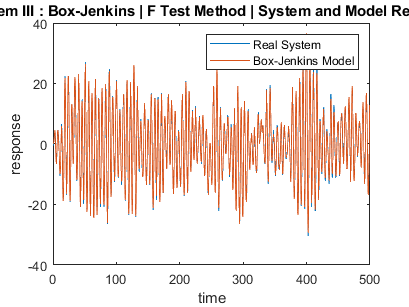


figure(4)
plot(t_val,y3_val,t_val,FTest_y_hat_3)
legend('Real System','Box-Jenkins Model')
title(" System III : Box-Jenkins | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

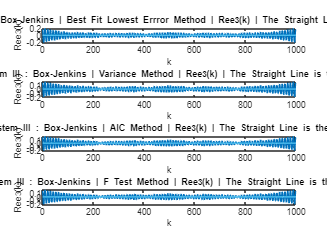

%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,bj_BestFit_Ree_3(2:end), 1:N_val-1, mean(bj_BestFit_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Box-Jenkins | Best Fit Lowest Errror Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,2)
plot(1:N_val-1,bj_Var_Ree_3(2:end), 1:N_val-1, mean(bj_Var_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Box-Jenkins | Variance Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,3)
plot(1:N_val-1,bj_AIC_Ree_3(2:end), 1:N_val-1, mean(bj_AIC_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Box-Jenkins | AIC Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(4,1,4)
plot(1:N_val-1,bj_FTest_Ree_3(2:end), 1:N_val-1, mean(bj_FTest_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Box-Jenkins | F Test Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

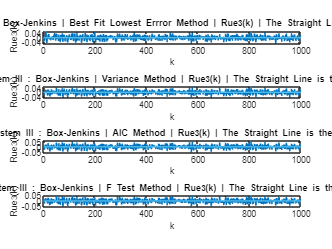

%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,bj_BestFit_Rue_3(2:end), 1:N_val-1, mean(bj_BestFit_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Box-Jenkins | Best Fit Lowest Errror Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,2)
plot(1:N_val-1,bj_Var_Rue_3(2:end), 1:N_val-1, mean(bj_Var_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Box-Jenkins | Variance Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,3)
plot(1:N_val-1,bj_AIC_Rue_3(2:end), 1:N_val-1, mean(bj_AIC_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Box-Jenkins | AIC Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(4,1,4)
plot(1:N_val-1,bj_FTest_Rue_3(2:end), 1:N_val-1, mean(bj_FTest_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : Box-Jenkins | F Test Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")